nvar = 2;
lb = [0 -5];
ub = [5 0];


                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            60                 1                 1
    2           120          0.146732          0.974613
    3           180         0.0871958          0.935637
    4           240         0.0453826          0.977382
    5           300         0.0355192          0.671169
    6           360         0.0302824          0.932952
    7           420         0.0224171          0.163086
    8           480         0.0190758          0.960984
    9           540         0.0193788          0.146624
   10           600         0.0232589          0.163284
   11           660         0.0196356          0.136401
   12           720         0.0209066          0.153754
   13           780         0.0239126          0.903857
   14           840         0.0141499          0.857469
   15           900          0.017911          0.131635
   16           960         0.0187837     

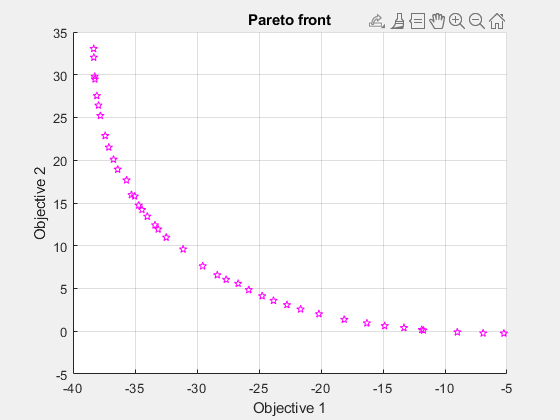

% Set nondefault solver options
options = optimoptions('gamultiobj','PopulationSize',60,'ParetoFraction',0.7,...
    'Display','iter','PlotFcn','gaplotpareto');

% Solve
[solution,objectiveValue] = gamultiobj(@multiObjFcn,nvar,[],[],[],[],lb,ub,...
    [],options);


% Clear variables
clearvars options

function F = multiObjFcn(optimInput)
% Example:
% Minimize F(x,y) where
% F(1) = x^2 + y^2
% F(2) = 2 + 0.5*((x-2)^2 + (y+1)^2)

% Edit the lines below with your calculation
x = optimInput;
f(2) = x(1)^4 + x(2)^4 + x(1)*x(2) - (x(1)*x(2))^2;
f(1) = f(2) - 10*x(1)^2;
F = f;
end
